### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\CircuitoComplejoStubs.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 11×7 cell array
    {'C2'  }    {'N003'}    {'N001'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C3'  }    {'N004'}    {'N003'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C4'  }    {'N005'}    {'N004'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C5'  }    {'N007'}    {'N006'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R1'  }    {'N003'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R2'  }    {'N005'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R3'  }    {'N007'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'L1'  }    {'N006'}    {'0'   }    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'SSC1'}    {'N004'}    {'0'   }    {'SSC'}    {[   62.8300]}    {[45]}    {[1.0000e+09]}
    {'SOC1'}    {'N005'}    {'N006'}    {'SOC'}    {[   13.2600]}    {[45]}    {[1.0000e+09]}
    {'SOC2'}    {'N007'}    {'


% Metodo Objeto Circuito Matlab
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubCorto'
                    Z0: 62.8300
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Short'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


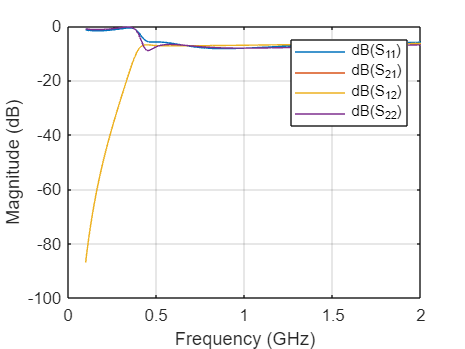

rfplot(SMatlab4);


% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nuevo_Netlist = 11×7 cell array
    {'C2'  }    {'N003'}    {'N001'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C3'  }    {'N004'}    {'N003'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C4'  }    {'N005'}    {'N004'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C5'  }    {'N007'}    {'N006'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R1'  }    {'N003'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R2'  }    {'N005'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R3'  }    {'N007'}    {'0'   }    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'L1'  }    {'N006'}    {'0'   }    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'SSC1'}    {'N004'}    {'0'   }    {'SSC'}    {[   62.8300]}    {[45]}    {[1.0000e+09]}
    {'SOC1'}    {'N005'}    {'N006'}    {'SOC'}    {[   13.2600]}    {[45]}    {[1.0000e+09]}
    {'SOC2'}    {'N007'}    

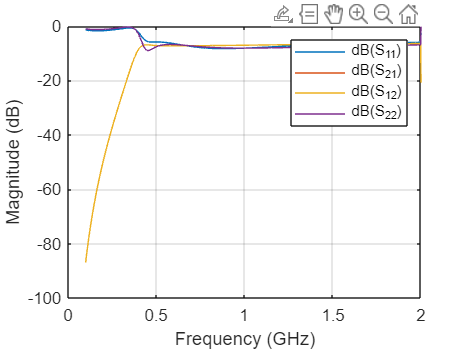

Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=z2s(Matriz_Z,50);

freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


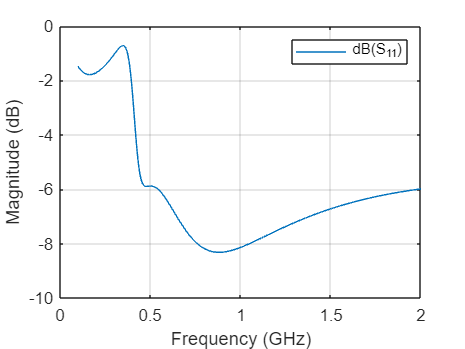


rfplot(SMatlab4,1,1)

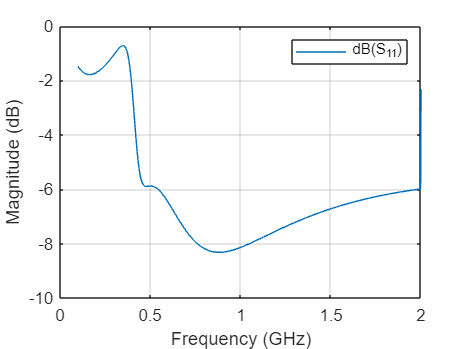

rfplot(SParamsObject,1,1)